clear; gcp; % start a parallel engine

Starting parallel pool (parpool) using the 'local' profile ...




% Find base repository path (where this file is contained)
basePath = fileparts(which('demo_MMM_pipeline'));
% Add to MATLAB path
idcs   = strfind(basePath,filesep);
addpath(genpath(fullfile(basePath(1:idcs(end)-1))));

% Download dataset using link in the README
% load
load('jointsCON.mat')

## Data in Brief

% brief data description
for i=1:size(jointsCON,2)
    disp(['group_', num2str(i), ' - ', num2str(size(jointsCON{1,i},1)),...
        ' ', jointsCON{2,i},' ', jointsCON{3,i},' mice', ' cross ',num2str(size(jointsCON{1,i},2)),' days'])
end

group_1 - 14 Cntnap2 negative mice cross 4 days
group_2 - 15 Cntnap2 heterozygote mice cross 4 days
group_3 - 10 Cntnap2 homozygote mice cross 4 days
group_4 - 17 L7-Cre-Tsc1 negative mice cross 4 days
group_5 - 17 L7-Cre-Tsc1 heterozygote mice cross 4 days
group_6 - 9 L7-Cre-Tsc1 homozygote mice cross 4 days
group_7 - 60 B6 male negative mice cross 5 days
group_8 - 20 B6 female negative mice cross 5 days


% select which body parts to use in pipeline

xIdx = [1 2 5 6 7 8 12 13 14 15 16];
yIdx = [1 2 5 6 7 8 12 13 14 15 16];

[X,Y] = meshgrid(xIdx,yIdx);
X = X(:); Y = Y(:);
IDX = find(X~=Y);

## do online PCA to find modes

batchSize = 20000;
firstBatch = true;
currentImage = 0;

for g = 1:size(jointsCON,2)
    for i = 1:size(jointsCON{1,g},1)
        fprintf(1,['Processing data for mouse ' num2str(i) ' from group_' num2str(g) '\n']);
        for j = 1:size(jointsCON{1,g},2)
            if ~isempty(jointsCON{1,g}{i,j})
                
                % calculate distances from body part positions
                p1 = jointsCON{1,g}{i,j};
                p1Dist = zeros(size(X,1),size(p1,3));
                for ii = 1:size(p1Dist,1)
                    p1Dist(ii,:) = returnDist(squeeze(p1(X(ii),:,:)),squeeze(p1(Y(ii),:,:)));
                end
                
                p1Dsmooth = zeros(size(p1Dist));
                for ii = 1:size(p1Dist,1)
                    p1Dsmooth(ii,:) = medfilt1(smooth(p1Dist(ii,:),5),5);
                end
                p1Dist = p1Dsmooth(IDX,:);
                
                if firstBatch
                    firstBatch = false;
                    if size(p1Dist,2)<batchSize
                        cBatchSize = size(p1Dist,2);
                        XX = p1Dist';
                    else
                        cBatchSize = batchSize;
                        XX = p1Dist(:,randperm(size(p1Dist,2),cBatchSize))';
                    end
                    
                    currentImage = batchSize;
                    muv = sum(XX);
                    C = cov(XX).*batchSize + (muv'*muv)./cBatchSize;
                else
                    if size(p1Dist,2)<batchSize
                        cBatchSize = size(p1Dist,2);
                        XX = p1Dist';
                    else
                        cBatchSize = batchSize;
                        XX = p1Dist(:,randperm(size(p1Dist,2),cBatchSize))';
                    end
                    
                    tempMu = sum(XX);
                    muv = muv+tempMu;
                    C = C + cov(XX).*cBatchSize + (tempMu'*tempMu)./cBatchSize;
                    currentImage = currentImage + cBatchSize;
                    pause(.1)
                    fprintf(1,[num2str(currentImage),'\n'])
                end
                
            else
            end
            
        end
    end
end

Processing data for mouse 1 from group_1


40000
60000
80000


Processing data for mouse 2 from group_1


100000
120000
140000
160000


Processing data for mouse 3 from group_1


180000
200000
220000
240000


Processing data for mouse 4 from group_1


260000
280000
300000
320000


Processing data for mouse 5 from group_1


340000
360000
380000
400000


Processing data for mouse 6 from group_1


420000
440000
460000
480000


Processing data for mouse 7 from group_1


500000
520000
540000
560000


Processing data for mouse 8 from group_1


580000
600000
620000
640000


Processing data for mouse 9 from group_1


660000
680000
700000
720000


Processing data for mouse 10 from group_1


740000
760000
780000
800000


Processing data for mouse 11 from group_1


820000
840000
860000
880000


Processing data for mouse 12 from group_1


900000
920000
940000
960000


Processing data for mouse 13 from group_1


980000
1000000
1020000
1040000


Processing data for mouse 14 from group_1


1060000
1080000
1100000
1120000


Processing data for mouse 1 from group_2


1140000
1160000
1180000
1200000


Processing data for mouse 2 from group_2


1220000
1240000
1260000
1280000


Processing data for mouse 3 from group_2


1300000
1320000
1340000
1360000


Processing data for mouse 4 from group_2


1380000
1400000
1420000
1440000


Processing data for mouse 5 from group_2


1460000
1480000
1500000
1520000


Processing data for mouse 6 from group_2


1540000
1560000
1580000
1600000


Processing data for mouse 7 from group_2


1620000
1640000
1660000
1680000


Processing data for mouse 8 from group_2


1700000
1720000
1740000
1760000


Processing data for mouse 9 from group_2


1780000
1800000
1820000
1840000


Processing data for mouse 10 from group_2


1860000
1880000
1900000
1920000


Processing data for mouse 11 from group_2


1940000
1960000
1980000
2000000


Processing data for mouse 12 from group_2


2020000
2040000
2060000
2080000


Processing data for mouse 13 from group_2


2100000
2120000
2140000
2160000


Processing data for mouse 14 from group_2


2180000
2200000
2220000
2240000


Processing data for mouse 15 from group_2


2260000
2280000
2300000
2320000


Processing data for mouse 1 from group_3


2340000
2360000
2380000
2400000


Processing data for mouse 2 from group_3


2420000
2440000
2460000
2480000


Processing data for mouse 3 from group_3


2500000
2520000
2540000
2560000


Processing data for mouse 4 from group_3


2580000
2600000
2620000
2640000


Processing data for mouse 5 from group_3


2660000
2680000
2700000
2720000


Processing data for mouse 6 from group_3


2740000
2760000
2780000
2800000


Processing data for mouse 7 from group_3


2820000
2840000
2860000
2880000


Processing data for mouse 8 from group_3


2900000
2920000
2940000
2960000


Processing data for mouse 9 from group_3


2980000
3000000
3020000
3040000


Processing data for mouse 10 from group_3


3060000
3080000
3100000
3120000


Processing data for mouse 1 from group_4


3140000
3160000
3180000
3200000


Processing data for mouse 2 from group_4


3220000
3240000
3260000
3280000


Processing data for mouse 3 from group_4


3300000
3320000
3340000
3360000


Processing data for mouse 4 from group_4


3380000
3400000
3420000
3440000


Processing data for mouse 5 from group_4


3460000
3480000
3500000
3520000


Processing data for mouse 6 from group_4


3540000
3560000
3580000
3600000


Processing data for mouse 7 from group_4


3620000
3640000
3660000
3680000


Processing data for mouse 8 from group_4


3700000
3720000
3740000
3760000


Processing data for mouse 9 from group_4


3780000
3800000
3820000
3840000


Processing data for mouse 10 from group_4


3860000
3880000
3900000
3920000


Processing data for mouse 11 from group_4


3940000
3960000
3980000
4000000


Processing data for mouse 12 from group_4


4020000
4040000
4060000
4080000


Processing data for mouse 13 from group_4


4100000
4120000
4140000
4160000


Processing data for mouse 14 from group_4


4180000
4200000
4220000
4240000


Processing data for mouse 15 from group_4


4260000
4280000
4300000
4320000


Processing data for mouse 16 from group_4


4340000
4360000
4380000
4400000


Processing data for mouse 17 from group_4


4420000
4440000
4460000
4480000


Processing data for mouse 1 from group_5


4500000
4520000
4540000
4560000


Processing data for mouse 2 from group_5


4580000
4600000
4620000
4640000


Processing data for mouse 3 from group_5


4660000
4680000
4700000
4720000


Processing data for mouse 4 from group_5


4740000
4760000
4780000
4800000


Processing data for mouse 5 from group_5


4820000
4840000
4860000
4880000


Processing data for mouse 6 from group_5


4900000
4920000
4940000
4960000


Processing data for mouse 7 from group_5


4980000
5000000
5020000
5040000


Processing data for mouse 8 from group_5


5060000
5080000
5100000
5120000


Processing data for mouse 9 from group_5


5140000
5160000
5180000
5200000


Processing data for mouse 10 from group_5


5220000
5240000
5260000
5280000


Processing data for mouse 11 from group_5


5300000
5320000
5340000
5360000


Processing data for mouse 12 from group_5


5380000
5400000
5420000
5440000


Processing data for mouse 13 from group_5


5460000
5480000
5500000
5520000


Processing data for mouse 14 from group_5


5540000
5560000
5580000
5600000


Processing data for mouse 15 from group_5


5620000
5640000
5660000
5680000


Processing data for mouse 16 from group_5


5700000
5720000
5740000
5760000


Processing data for mouse 17 from group_5


5780000
5800000
5820000
5840000


Processing data for mouse 1 from group_6


5860000
5880000
5900000
5920000


Processing data for mouse 2 from group_6


5940000
5960000
5980000
6000000


Processing data for mouse 3 from group_6


6020000
6040000
6060000
6080000


Processing data for mouse 4 from group_6


6100000
6120000
6140000
6160000


Processing data for mouse 5 from group_6


6180000
6200000
6220000
6240000


Processing data for mouse 6 from group_6


6260000
6280000
6300000
6320000


Processing data for mouse 7 from group_6


6340000
6360000
6380000
6400000


Processing data for mouse 8 from group_6


6420000
6440000
6460000
6480000


Processing data for mouse 9 from group_6


6500000
6520000
6540000
6560000


Processing data for mouse 1 from group_7


6580000
6600000
6620000
6640000
6660000


Processing data for mouse 2 from group_7


6680000
6700000
6720000
6740000
6760000


Processing data for mouse 3 from group_7


6780000
6800000
6820000
6840000
6860000


Processing data for mouse 4 from group_7


6880000
6900000
6920000
6940000
6960000


Processing data for mouse 5 from group_7


6980000
7000000
7020000
7040000
7060000


Processing data for mouse 6 from group_7


7080000
7100000
7120000
7140000
7160000


Processing data for mouse 7 from group_7


7180000
7200000
7220000
7240000
7260000


Processing data for mouse 8 from group_7


7280000
7300000
7320000
7340000
7360000


Processing data for mouse 9 from group_7


7380000
7400000
7420000
7440000
7460000


Processing data for mouse 10 from group_7


7480000
7500000
7520000
7540000
7560000


Processing data for mouse 11 from group_7


7580000
7600000
7620000
7640000
7660000


Processing data for mouse 12 from group_7


7680000
7700000
7720000
7740000
7760000


Processing data for mouse 13 from group_7


7780000
7800000
7820000
7840000
7860000


Processing data for mouse 14 from group_7


7880000
7900000
7920000
7940000
7960000


Processing data for mouse 15 from group_7


7980000
8000000
8020000
8040000
8060000


Processing data for mouse 16 from group_7


8080000
8100000
8120000
8140000
8160000


Processing data for mouse 17 from group_7


8180000
8200000
8220000
8240000
8260000


Processing data for mouse 18 from group_7


8280000
8300000
8320000
8340000
8360000


Processing data for mouse 19 from group_7


8380000
8400000
8420000
8440000
8460000


Processing data for mouse 20 from group_7


8480000
8500000
8520000
8540000
8560000


Processing data for mouse 21 from group_7


8580000
8600000
8620000
8640000
8660000


Processing data for mouse 22 from group_7


8680000
8700000
8720000
8740000
8760000


Processing data for mouse 23 from group_7


8780000
8800000
8820000
8840000
8860000


Processing data for mouse 24 from group_7


8880000
8900000
8920000
8940000
8960000


Processing data for mouse 25 from group_7


8980000
9000000
9020000
9040000
9060000


Processing data for mouse 26 from group_7


9080000
9100000
9120000
9140000
9160000


Processing data for mouse 27 from group_7


9180000
9200000
9220000
9240000
9260000


Processing data for mouse 28 from group_7


9280000
9300000
9320000
9340000
9360000


Processing data for mouse 29 from group_7


9380000
9400000
9420000
9440000
9460000


Processing data for mouse 30 from group_7


9480000
9500000
9520000
9540000
9560000


Processing data for mouse 31 from group_7


9580000
9600000
9620000
9640000
9660000


Processing data for mouse 32 from group_7


9680000
9700000
9720000
9740000
9760000


Processing data for mouse 33 from group_7


9780000
9800000
9820000
9840000
9860000


Processing data for mouse 34 from group_7


9880000
9900000
9920000
9940000
9960000


Processing data for mouse 35 from group_7


9980000
10000000
10020000
10040000
10060000


Processing data for mouse 36 from group_7


10080000
10100000
10120000
10140000
10160000


Processing data for mouse 37 from group_7


10180000
10200000
10220000
10240000
10260000


Processing data for mouse 38 from group_7


10280000
10300000
10320000
10340000
10360000


Processing data for mouse 39 from group_7


10380000
10400000
10420000
10440000
10460000


Processing data for mouse 40 from group_7


10480000
10500000
10520000
10540000
10560000


Processing data for mouse 41 from group_7


10580000
10600000
10620000
10640000
10660000


Processing data for mouse 42 from group_7


10680000
10700000
10720000
10740000
10760000


Processing data for mouse 43 from group_7


10780000
10800000
10820000
10840000
10860000


Processing data for mouse 44 from group_7


10880000
10900000
10920000
10940000
10960000


Processing data for mouse 45 from group_7


10980000
11000000
11020000
11040000
11060000


Processing data for mouse 46 from group_7


11080000
11100000
11120000
11140000
11160000


Processing data for mouse 47 from group_7


11180000
11200000
11220000
11240000
11260000


Processing data for mouse 48 from group_7


11280000
11300000
11320000
11340000
11360000


Processing data for mouse 49 from group_7


11380000
11400000
11420000
11440000
11460000


Processing data for mouse 50 from group_7


11480000
11500000
11520000
11540000
11560000


Processing data for mouse 51 from group_7


11580000
11600000
11620000
11640000
11660000


Processing data for mouse 52 from group_7


11680000
11700000
11720000
11740000
11760000


Processing data for mouse 53 from group_7


11780000
11800000
11820000
11840000
11860000


Processing data for mouse 54 from group_7


11880000
11900000
11920000
11940000
11960000


Processing data for mouse 55 from group_7


11980000
12000000
12020000
12040000
12060000


Processing data for mouse 56 from group_7


12080000
12100000
12120000
12140000
12160000


Processing data for mouse 57 from group_7


12180000
12200000
12220000
12240000
12260000


Processing data for mouse 58 from group_7


12280000
12300000
12320000
12340000
12360000


Processing data for mouse 59 from group_7


12380000
12400000
12420000
12440000
12460000


Processing data for mouse 60 from group_7


12480000
12500000
12520000
12540000
12560000


Processing data for mouse 1 from group_8


12580000
12600000
12620000
12640000
12660000


Processing data for mouse 2 from group_8


12680000
12700000
12720000
12740000
12760000


Processing data for mouse 3 from group_8


12780000
12800000
12820000
12840000
12860000


Processing data for mouse 4 from group_8


12880000
12900000
12920000
12940000
12960000


Processing data for mouse 5 from group_8


12980000
13000000
13020000
13040000
13060000


Processing data for mouse 6 from group_8


13080000
13100000
13120000
13140000
13160000


Processing data for mouse 7 from group_8


13180000
13200000
13220000
13240000
13260000


Processing data for mouse 8 from group_8


13280000
13300000
13320000
13340000
13360000


Processing data for mouse 9 from group_8


13380000
13400000
13420000
13440000
13460000


Processing data for mouse 10 from group_8


13480000
13500000
13520000
13540000
13560000


Processing data for mouse 11 from group_8


13580000
13600000
13620000
13640000
13660000


Processing data for mouse 12 from group_8


13680000
13700000
13720000
13740000
13760000


Processing data for mouse 13 from group_8


13780000
13800000
13820000
13840000
13860000


Processing data for mouse 14 from group_8


13880000
13900000
13920000
13940000
13960000


Processing data for mouse 15 from group_8


13980000
14000000
14020000
14040000
14060000


Processing data for mouse 16 from group_8


14080000
14100000
14120000
14140000


Processing data for mouse 17 from group_8


14160000
14180000
14200000
14220000
14240000


Processing data for mouse 18 from group_8


14260000
14280000
14300000
14320000
14340000


Processing data for mouse 19 from group_8


14360000
14380000
14400000
14420000
14440000


Processing data for mouse 20 from group_8


14460000
14480000
14500000
14520000
14540000


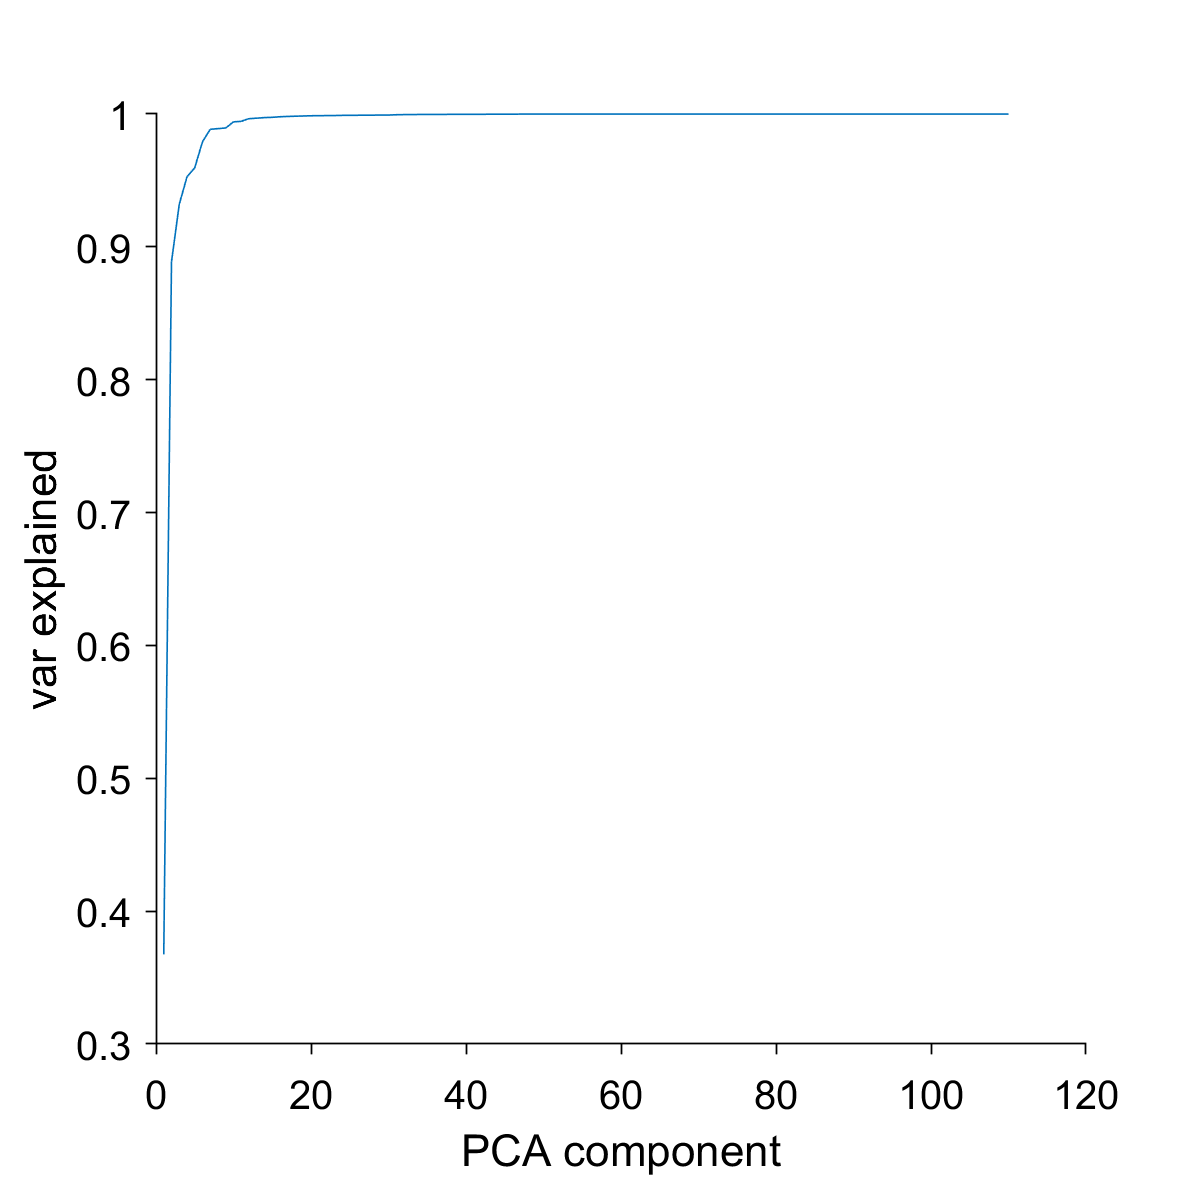

L = currentImage;
muv = muv./L;
C = C./L - muv'*muv;

[vecs,vals] = eig(C);
vals = flipud(diag(vals));
vecs = fliplr(vecs);
plot(1-(vals./sum(vals)))
prepfig;
xlabel('PCA component')
ylabel('var explained')

save('vecsVals_subSelect_demo.mat','C','muv','currentImage','vecs','vals');

## Project to PCA space, get wavelets and find data for training

% set papameters
dataAll = [];
numProjections = 10;
numModes = 10; pcaModes = numModes;
minF = .25; maxF = 20;

parameters = setRunParameters([]);
parameters.trainingSetSize = 80;
parameters.pcaModes = pcaModes;
parameters.samplingFreq = 80;
parameters.minF = minF;
parameters.maxF = maxF;
numPerDataSet = parameters.trainingSetSize;
numPoints = 5000;

## check parameters on single session

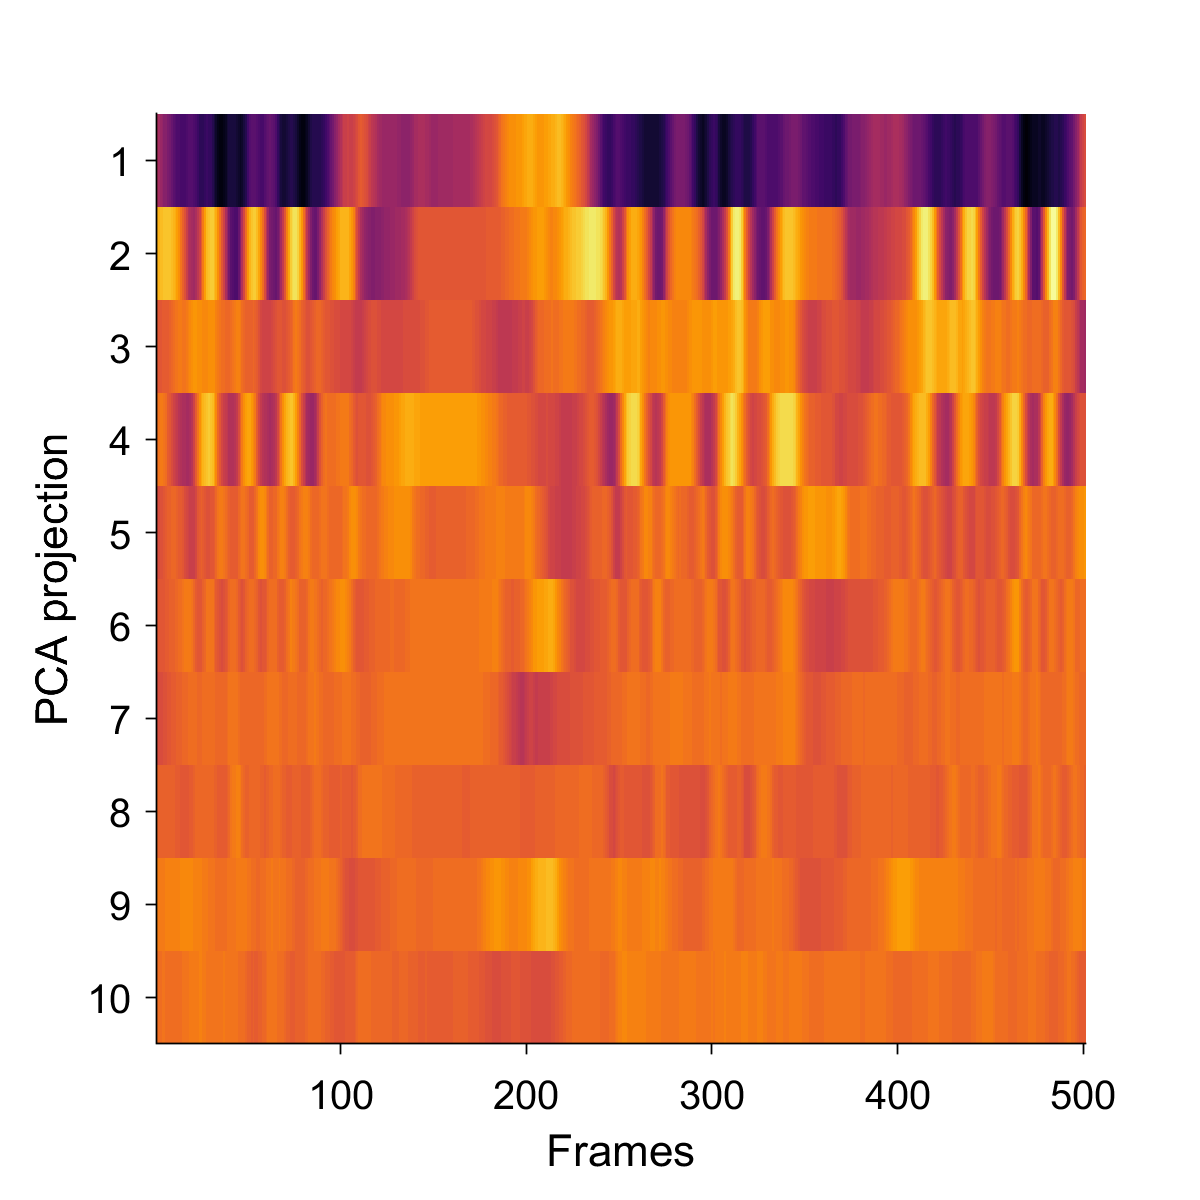

g=7; i=1; j=3;

% calculate distances from body part positions
p1 = jointsCON{1,g}{i,j};
p1Dist = zeros(size(X,1),size(p1,3));
for ii = 1:size(p1Dist,1)
    p1Dist(ii,:) = returnDist(squeeze(p1(X(ii),:,:)),squeeze(p1(Y(ii),:,:)));
end

p1Dsmooth = zeros(size(p1Dist));
for ii = 1:size(p1Dist,1)
    p1Dsmooth(ii,:) = medfilt1(smooth(p1Dist(ii,:),5),5);
end
p1Dist = p1Dsmooth(IDX,:);

p2Dist = bsxfun(@minus,p1Dist,muv');
projections = p2Dist'*vecs(:,1:numProjections);

figure;
imagesc(projections(4500:5000,:)');
colormap inferno
prepfig; ylabel('PCA projection'); xlabel('Frames');

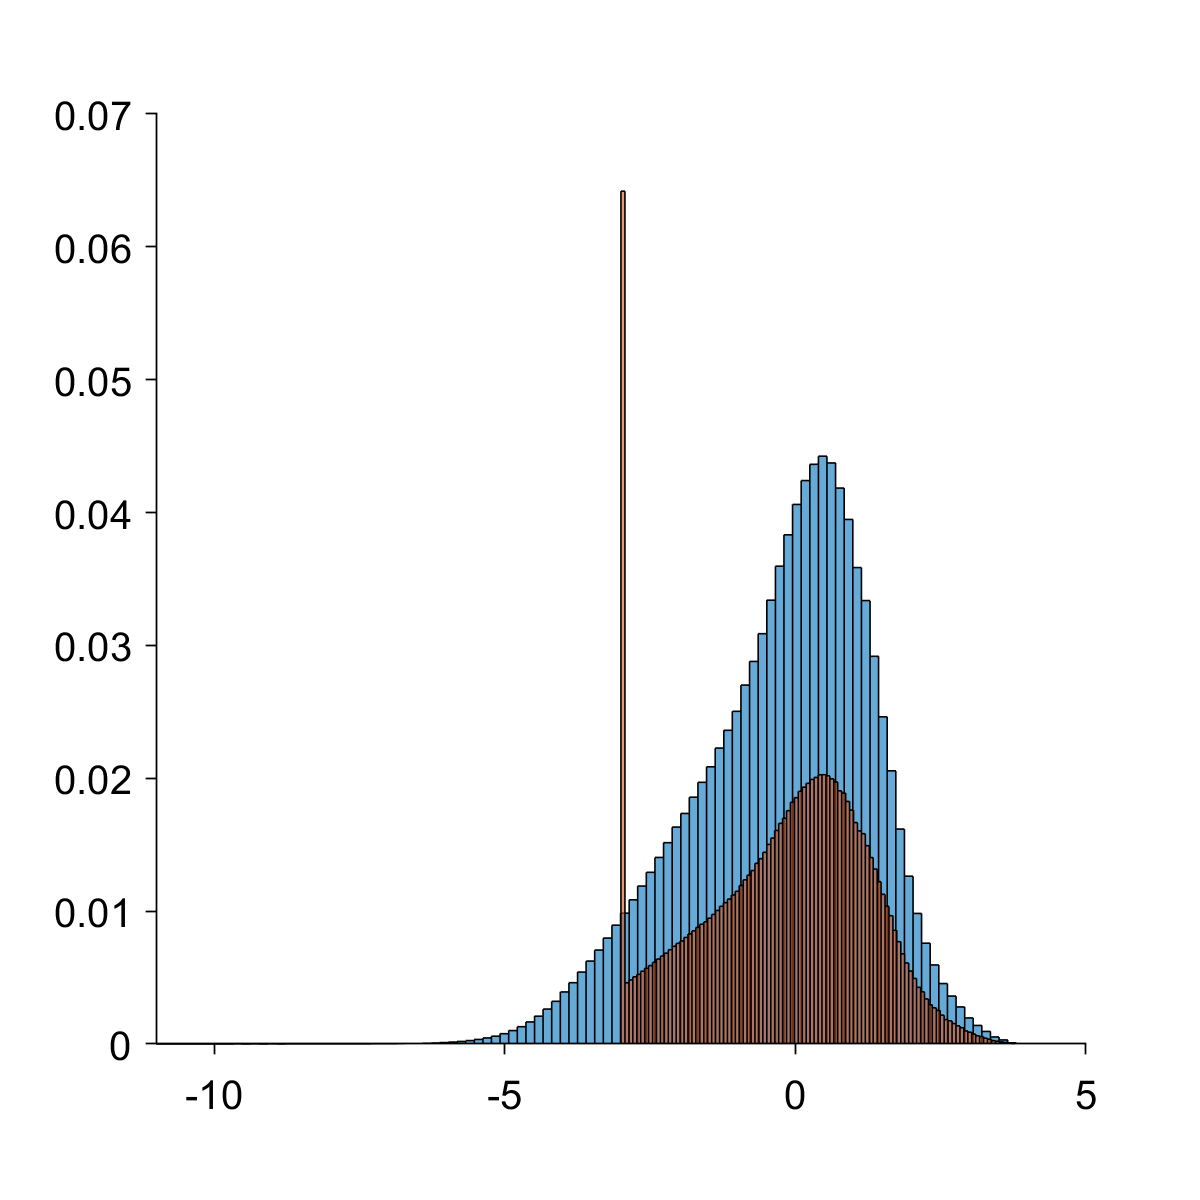

[data,~] = findWavelets(projections,numModes,parameters);
amps = sum(data,2);

data=log(data);
figure;
histogram(reshape(data,size(data,1)*size(data,2),1),100,'Normalization','probability'); hold on
data(data<-3) = -3;
histogram(reshape(data,size(data,1)*size(data,2),1),100,'Normalization','probability')
prepfig;

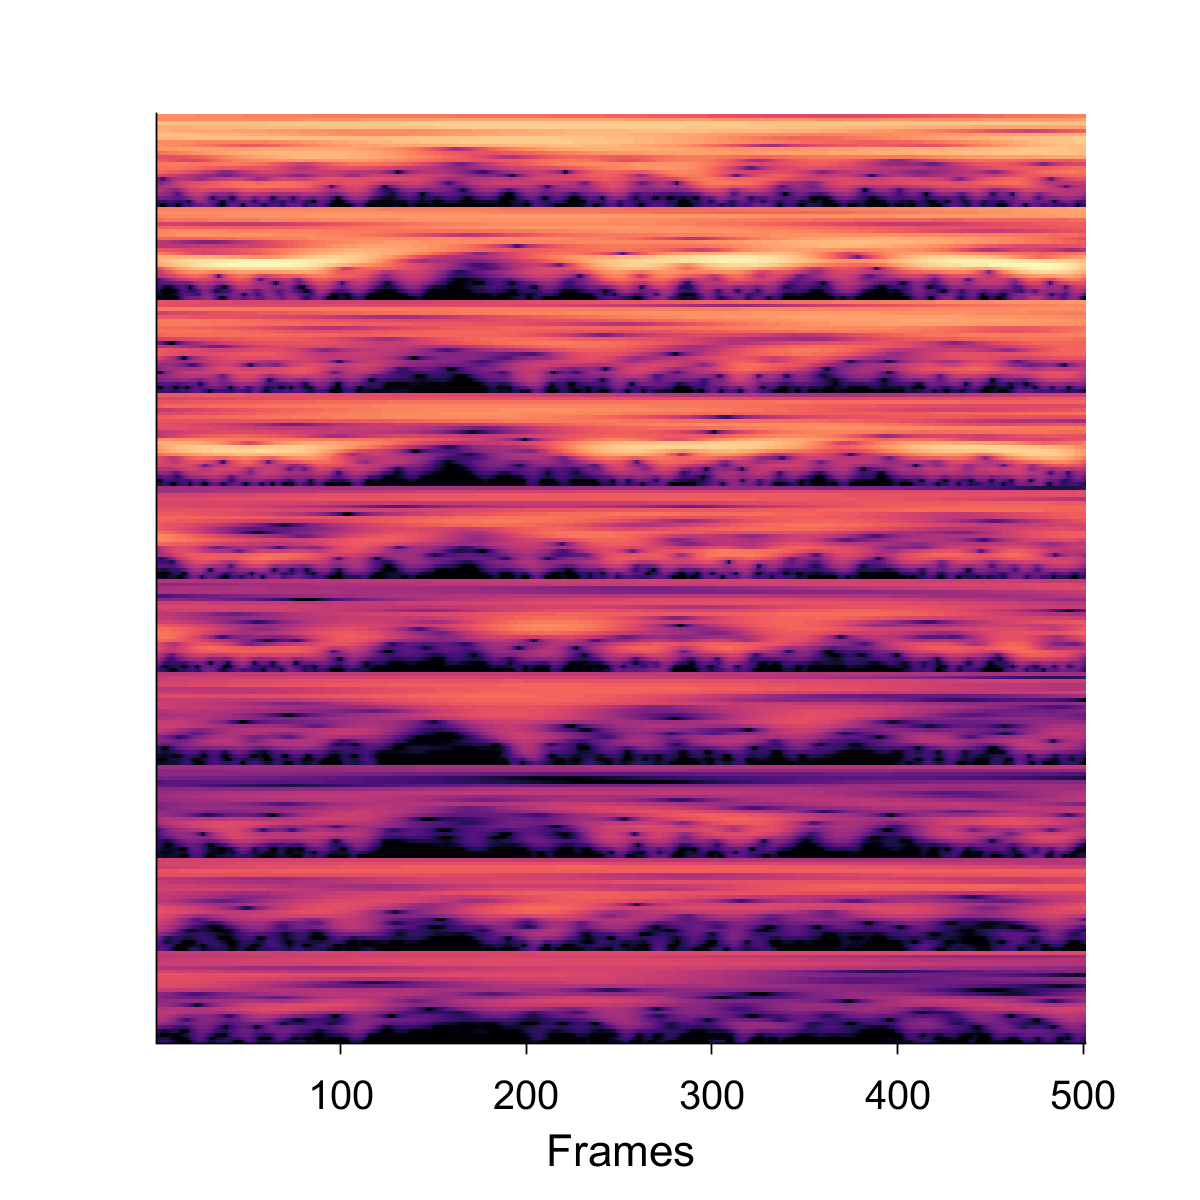

figure;
imagesc(data(4500:5000,:)');
colormap magma
prepfig; yticks([]); xlabel('Frames');

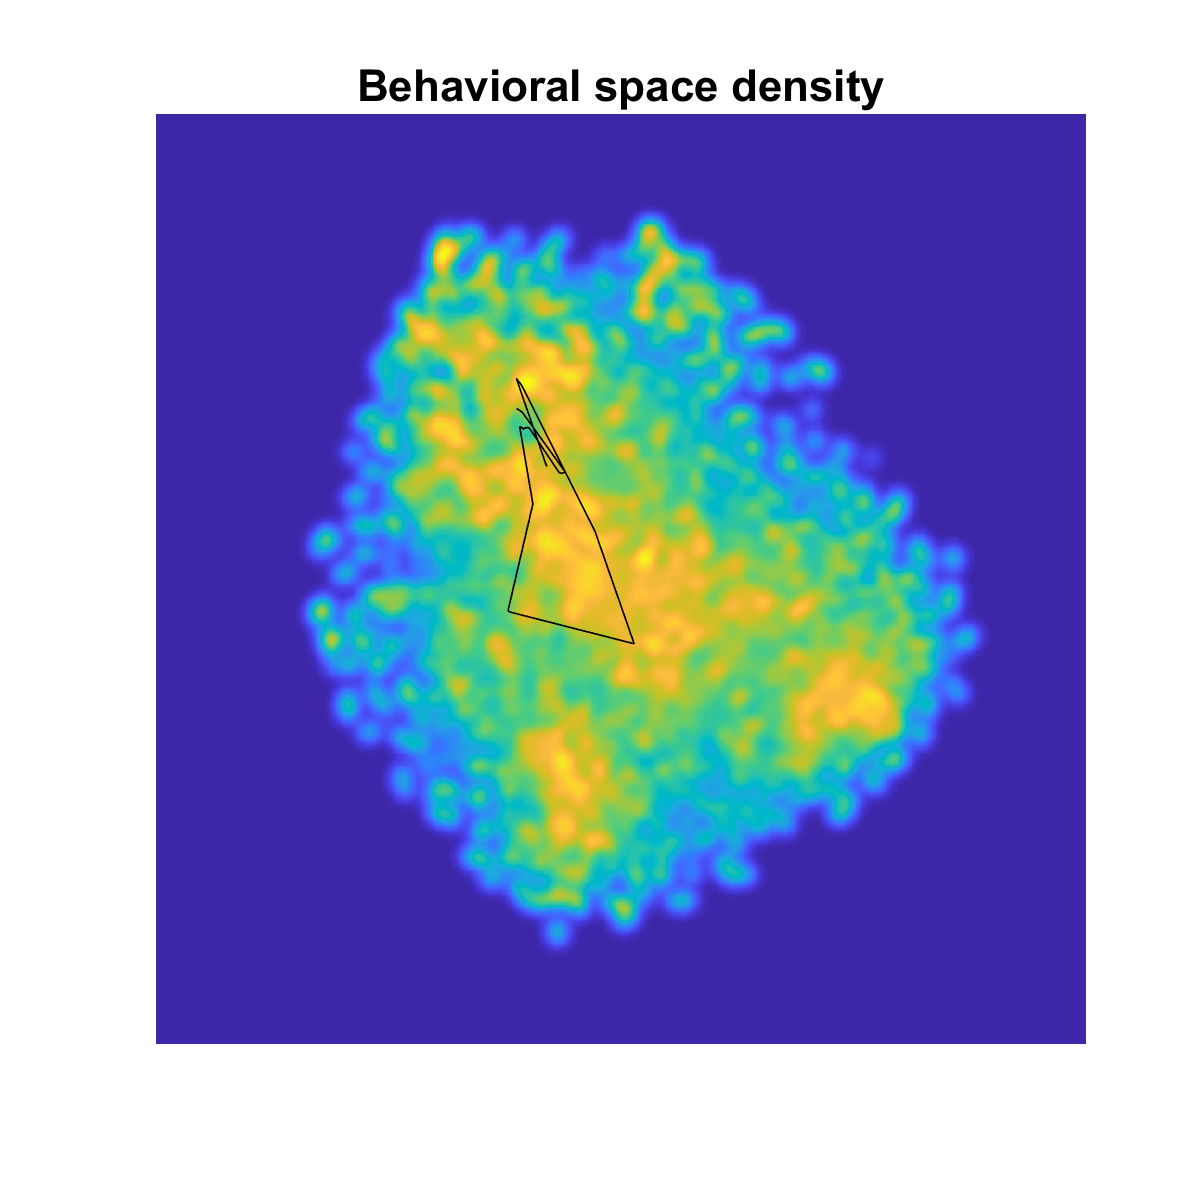

yData = tsne(data(1:10:end,:));
[xx,density,G,Z] = findPointDensity(yData, max(max(yData)) / 40, 501);
figure;
imagesc(xx,xx,density)
axis equal tight off xy
colormap parula
hold on;
plot(yData(450:500,2),yData(450:500,1),'k')
prepfig;
title('Behavioral space density')


[signalData,signalAmps] = findTemplatesFromData(...
    data,yData,amps,numPerDataSet,parameters);

	 Finding Templates


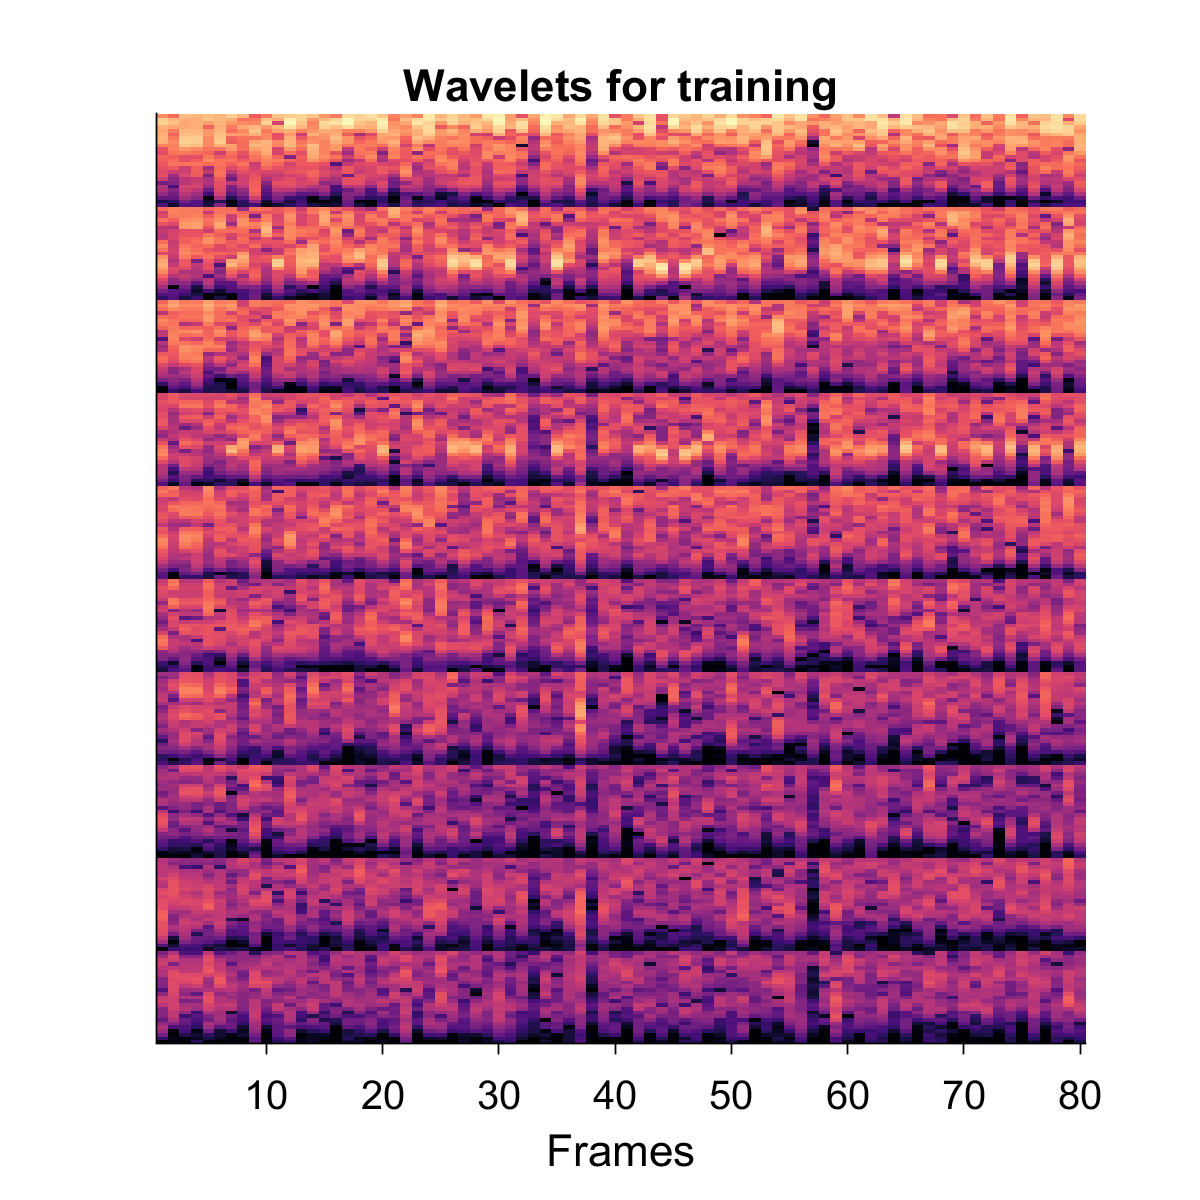

figure;
imagesc(signalData')
colormap magma
prepfig; yticks([]); xlabel('Frames');
title('Wavelets for training')

## Run parameters on full data set

dataAll = [];

for g = 1:size(jointsCON,2)
    for i = 1:size(jointsCON{1,g},1)
        fprintf(1,['Processing data for mouse ' num2str(i) ' from group_' num2str(g) '\n']);
        for j = 1:size(jointsCON{1,g},2)
            if ~isempty(jointsCON{1,g}{i,j})
                p1 = jointsCON{1,g}{i,j};
                p1Dist = zeros(size(X,1),size(p1,3));
                for ii = 1:size(p1Dist,1)
                    p1Dist(ii,:) = returnDist(squeeze(p1(X(ii),:,:)),squeeze(p1(Y(ii),:,:)));
                end
                
                p1Dsmooth = zeros(size(p1Dist));
                for ii = 1:size(p1Dist,1)
                    p1Dsmooth(ii,:) = medfilt1(smooth(p1Dist(ii,:),5),5);
                end
                p1Dist = p1Dsmooth(IDX,:);
                
                p2Dist = bsxfun(@minus,p1Dist,muv');
                projections = p2Dist'*vecs(:,1:numProjections);
                
                N = length(projections(:,1));
                numModes = parameters.pcaModes;
                skipLength = floor(N / numPoints);
                if skipLength == 0
                    skipLength = 1;
                    numPoints = N;
                else
                end
                
                firstFrame = mod(N,numPoints) + 1;
                signalIdx = firstFrame:skipLength:(firstFrame + (numPoints-1)*skipLength);
                
                signalAmps = amps(signalIdx);
                nnData = log(data(signalIdx,:));
                nnData(nnData<-3) = -3;
                
                yData = tsne(real(nnData));
                [signalData,signalAmps] = findTemplatesFromData(...
                    nnData,yData,signalAmps,numPerDataSet,parameters);
                
                dataAll = [dataAll; signalData];
                
            else
            end
        end
    end
end

Processing data for mouse 1 from group_1


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 2 from group_1


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 3 from group_1


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 4 from group_1


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 5 from group_1


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 6 from group_1


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 7 from group_1


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 8 from group_1


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 9 from group_1


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 10 from group_1


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 11 from group_1


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 12 from group_1


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 13 from group_1


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 14 from group_1


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 1 from group_2


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 2 from group_2


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 3 from group_2


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 4 from group_2


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 5 from group_2


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 6 from group_2


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 7 from group_2


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 8 from group_2


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 9 from group_2


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 10 from group_2


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 11 from group_2


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 12 from group_2


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 13 from group_2


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 14 from group_2


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 15 from group_2


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 1 from group_3


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 2 from group_3


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 3 from group_3


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 4 from group_3


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 5 from group_3


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 6 from group_3


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 7 from group_3


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 8 from group_3


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 9 from group_3


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 10 from group_3


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 1 from group_4


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 2 from group_4


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 3 from group_4


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 4 from group_4


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 5 from group_4


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 6 from group_4


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 7 from group_4


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 8 from group_4


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 9 from group_4


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 10 from group_4


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 11 from group_4


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 12 from group_4


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 13 from group_4


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 14 from group_4


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 15 from group_4


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 16 from group_4


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 17 from group_4


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 1 from group_5


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 2 from group_5


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 3 from group_5


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 4 from group_5


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 5 from group_5


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 6 from group_5


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 7 from group_5


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 8 from group_5


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 9 from group_5


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 10 from group_5


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 11 from group_5


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 12 from group_5


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 13 from group_5


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 14 from group_5


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 15 from group_5


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 16 from group_5


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 17 from group_5


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 1 from group_6


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 2 from group_6


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 3 from group_6


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 4 from group_6


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 5 from group_6


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 6 from group_6


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 7 from group_6


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 8 from group_6


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 9 from group_6


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 1 from group_7


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 2 from group_7


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 3 from group_7


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 4 from group_7


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 5 from group_7


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 6 from group_7


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 7 from group_7


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 8 from group_7


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 9 from group_7


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 10 from group_7


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 11 from group_7


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 12 from group_7


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 13 from group_7


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 14 from group_7


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 15 from group_7


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 16 from group_7


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 17 from group_7


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 18 from group_7


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 19 from group_7


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 20 from group_7


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 21 from group_7


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 22 from group_7


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 23 from group_7


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 24 from group_7


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 25 from group_7


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 26 from group_7


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 27 from group_7


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 28 from group_7


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 29 from group_7


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 30 from group_7


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 31 from group_7


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 32 from group_7


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 33 from group_7


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 34 from group_7


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 35 from group_7


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 36 from group_7


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 37 from group_7


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 38 from group_7


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 39 from group_7


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 40 from group_7


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 41 from group_7


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 42 from group_7


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 43 from group_7


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 44 from group_7


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 45 from group_7


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 46 from group_7


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 47 from group_7


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 48 from group_7


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 49 from group_7


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 50 from group_7


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 51 from group_7


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 52 from group_7


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 53 from group_7


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 54 from group_7


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 55 from group_7


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 56 from group_7


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 57 from group_7


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 58 from group_7


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 59 from group_7


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 60 from group_7


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 1 from group_8


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 2 from group_8


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 3 from group_8


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 4 from group_8


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 5 from group_8


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 6 from group_8


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 7 from group_8


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 8 from group_8


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 9 from group_8


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 10 from group_8


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 11 from group_8


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 12 from group_8


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 13 from group_8


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 14 from group_8


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 15 from group_8


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 16 from group_8


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 17 from group_8


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 18 from group_8


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 19 from group_8


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


Processing data for mouse 20 from group_8


	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates
	 Finding Templates


dataAll = real(dataAll);

## Embedding/Clustering

tic
ydata = tsne(dataAll);

toc

Elapsed time is 1431.009700 seconds.


tic
C100 = kmeans(dataAll,100,'Replicates',10);
toc

Elapsed time is 54.497904 seconds.


tic
C200 = kmeans(dataAll,200,'Replicates',10);
toc

Elapsed time is 75.798113 seconds.



save('trainingSet_demo.mat','dataAll','ydata','C100','C200');